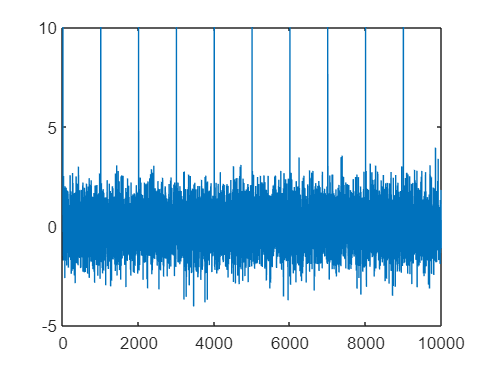

% Claim: If spikes are visible in time domain, they can be seen in
% frequency domain using FFT.

N = 10000;
spike_lags = 1000; % distance between spikes
y = randn(N,1);
y(1:spike_lags:end) = 10;  % Add visible spikes
plot(y);

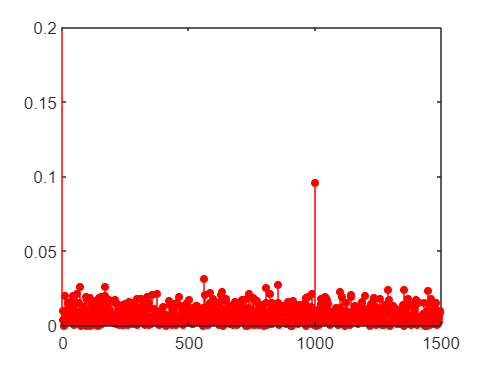

% Find spikes using FFT

length_FFT = 2^(nextpow2(length(y))+1); % exponent length

F = fft(y,length_FFT);  % fourier transform
F = F.*conj(F);  % element-wise complex conjugate
acf = ifft(F);  % take the inverse

numLags = 1500;  % number of lags to inspect

acf = acf(1:(numLags+1)); % Look at positive lags
acf = real(acf);  % only the real component

acf = acf./acf(1); % Normalize

%% plot

ax = gca;
lags = (0:numLags)';
Plot = stem(ax,lags,acf,'filled','r-o','MarkerSize',4,'Tag','ACF');
ylim([0 0.2])

## Hint: write "open xcorr.m" in terminal and look at line 173, matlab also uses FFT to calculate cross- and autocorrelation. Further reading: 

[https://en.wikipedia.org/wiki/Wiener%E2%80%93Khinchin_theorem](https://en.wikipedia.org/wiki/Wiener%E2%80%93Khinchin_theorem)

"the [Wiener–Khinchin theorem](https://en.wikipedia.org/wiki/Wiener%E2%80%93Khinchin_theorem) allows computing the autocorrelation from the raw data *X*(*t*) with two [fast Fourier transforms](https://en.wikipedia.org/wiki/Fast_Fourier_transform) (FFT) where IFFT denotes the inverse [fast Fourier transform](https://en.wikipedia.org/wiki/Fast_Fourier_transform). The asterisk denotes [complex conjugate](https://en.wikipedia.org/wiki/Complex_conjugate)."

[https://en.wikipedia.org/wiki/Autocorrelation](https://en.wikipedia.org/wiki/Autocorrelation)